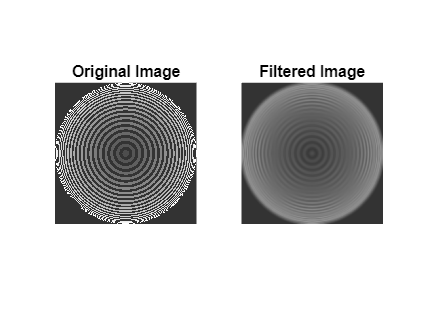

% Read the image
im = imread('zoneplate.tif');

filterSizeLarge = 30;  
filterSizeSmall = 8;   

% lower cutoff frequency
lp1 = fspecial('average', [filterSizeLarge filterSizeLarge]);

% higher cutoff frequency
lp2 = fspecial('average', [filterSizeSmall filterSizeSmall]);

filteredImage = myfilter(im, lp1, lp2);


figure;
subplot(1, 2, 1);
imshow(im);
title('Original Image');

subplot(1, 2, 2);
imshow(filteredImage);
title('Filtered Image');

test1 = imread('test1.tif');
test2 = imread('test2.tif');
test3 = imread('test3.tif');
test4 = imread('test4.tif');
q = [2, 2, 11, 2];


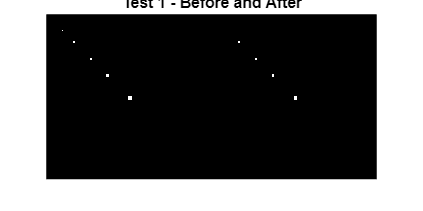

output1 = eliminateobjects(test1, q(1)+1);
figure;
imshowpair(test1, output1, 'montage');
title('Test 1 - Before and After');

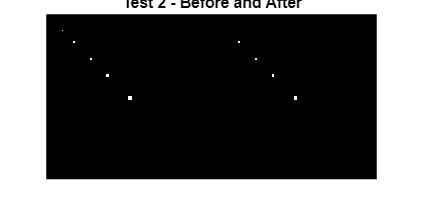

output2 = eliminateobjects(test2, q(2)+1);
figure; 
imshowpair(test2, output2, 'montage');
title('Test 2 - Before and After');

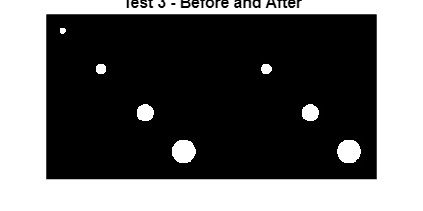

output3 = eliminateobjects(test3, q(3)+1);
figure; 
imshowpair(test3, output3, 'montage');
title('Test 3 - Before and After');

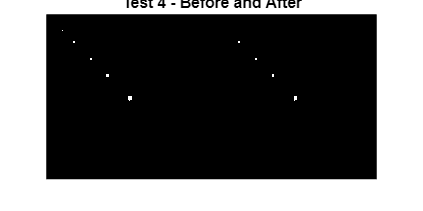

output4 = eliminateobjects(test4, q(4)+1);
figure; 
imshowpair(test4, output4, 'montage');
title('Test 4 - Before and After');